# ET-284 --- Assignment II

# Simulating radar with noncoherent integration of 100 pulses.

## João Vinholi

## Initialize Radar Object.

radobj = RadarSimulator;

ans =   RadarSimulator with properties:

               antenna_rpm: 12
             beam_aperture: 3
                         c: 300000000
                    dcycle: 0.0040
                      dSNR: 20
                      dvdt: 0
                        fp: 100000000
                        Gt: 1
                        Gr: 1
                         L: 6
                     Nofig: 0
                        Pt: 100000
                         R: 600
                     Sigma: 1
               SimDuration: 2
                        Tp: 1.0000e-06
                       V_0: 100
              acceleration: 30
    npulses_per_prediction: 100
                rangegates: [1×1250 double]
                 range_res: 30
                        fs: 5000000
                        gd: 4
                      hant: [1×1 phased.IsotropicAntennaElement]
                      hcol: [1×1 phased.Collector]
                 

sim_duration = 5; % time in seconds to simulate.

## SNR = -5 dB.

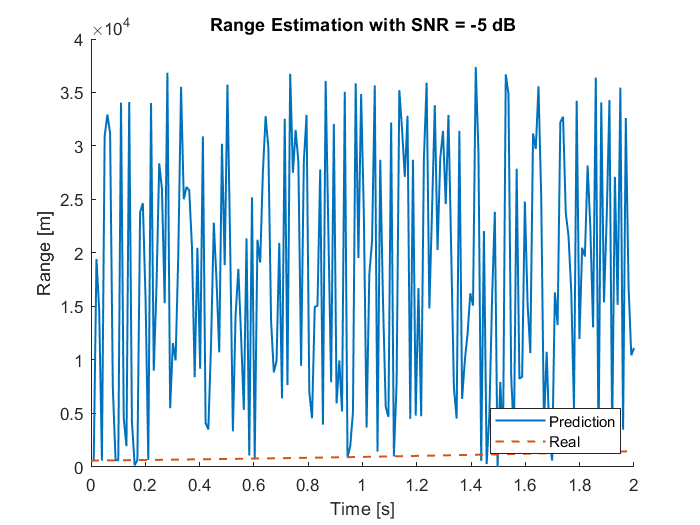

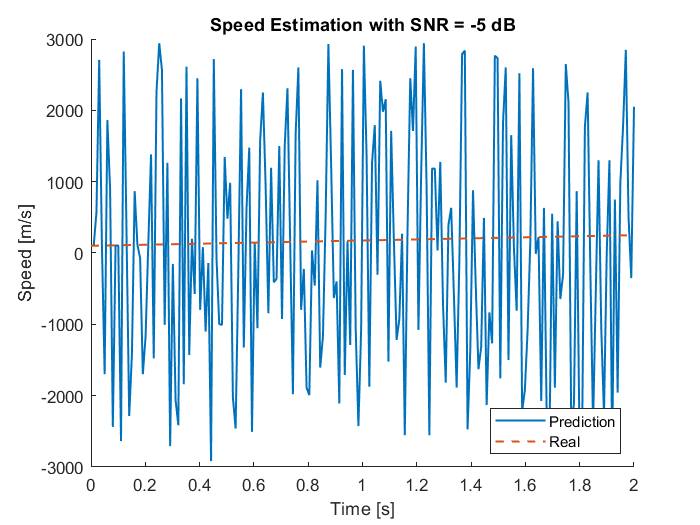

radobj.dSNR = -5; % dB
radobj = update_parameters(radobj);
result_struct_0 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_0, radobj)

## SNR = 0 dB.

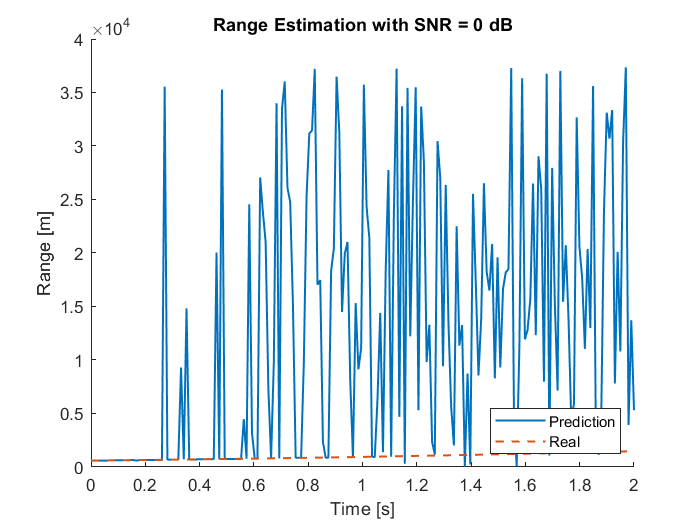

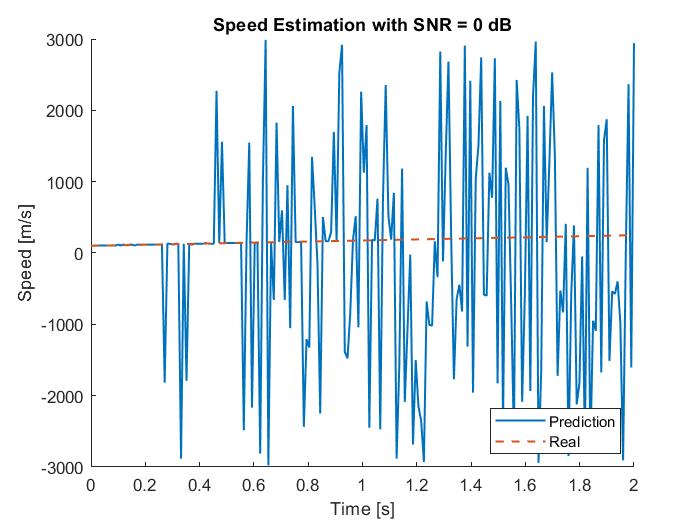

radobj.dSNR = 0; % dB
radobj = update_parameters(radobj);
result_struct_1 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_1, radobj)

## SNR = 5 dB.

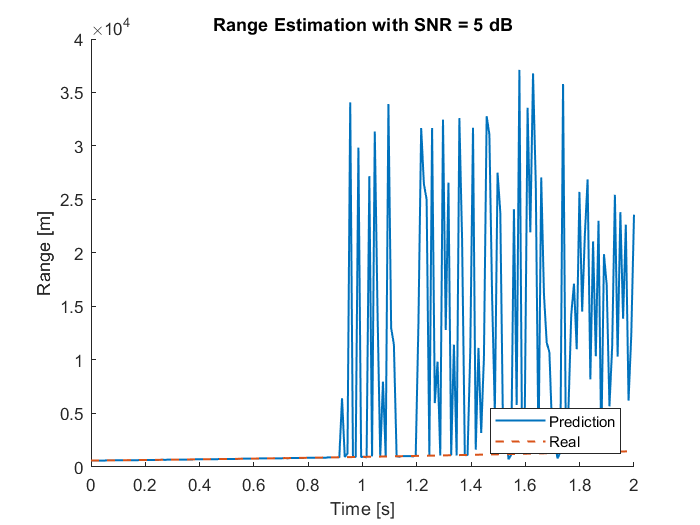

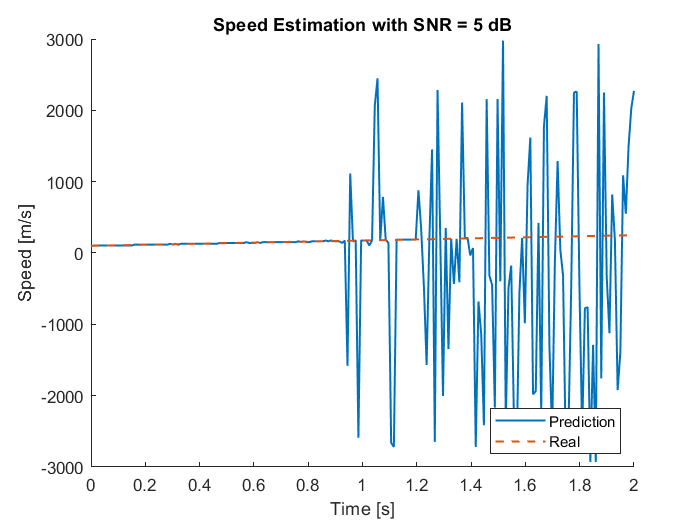

radobj.dSNR = 5; % dB
radobj = update_parameters(radobj);
result_struct_2 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_2, radobj)

## SNR = 10 dB.

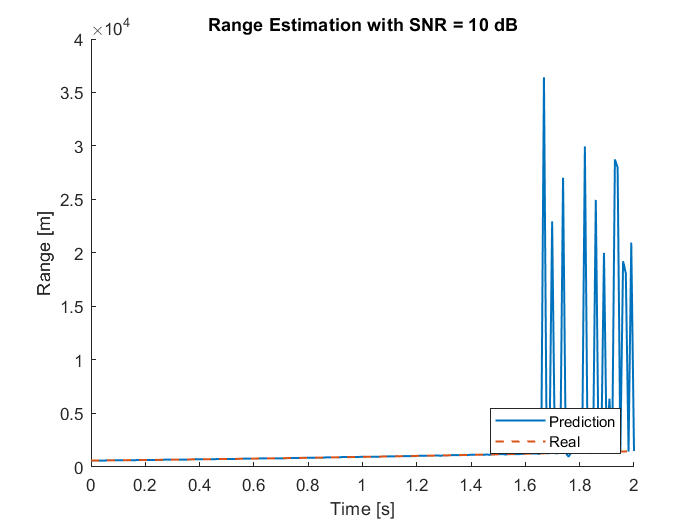

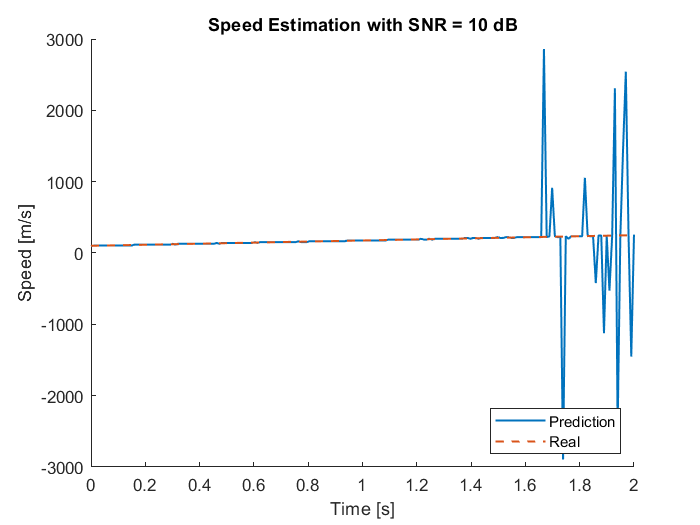

radobj.dSNR = 10; % dB
radobj = update_parameters(radobj);
result_struct_3 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_3, radobj)

## SNR = 15 dB.

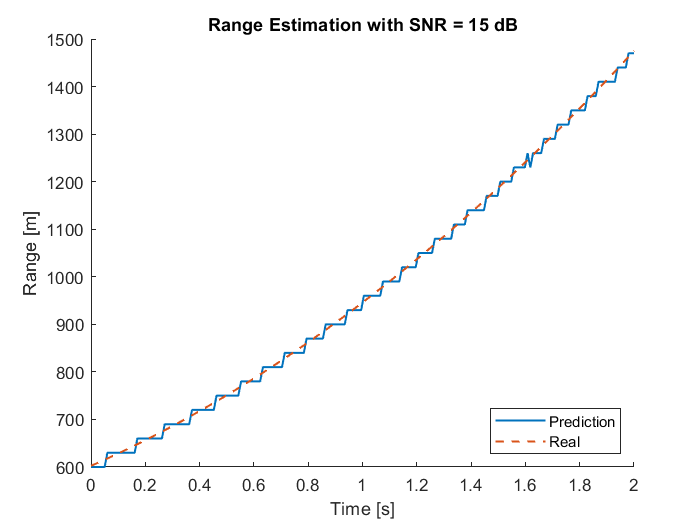

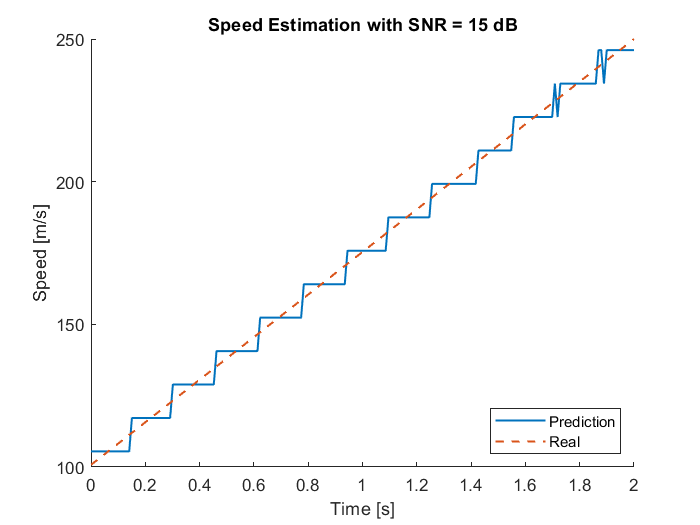

radobj.dSNR = 15; % dB
radobj = update_parameters(radobj);
result_struct_4 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_4, radobj)

## SNR = 20 dB.

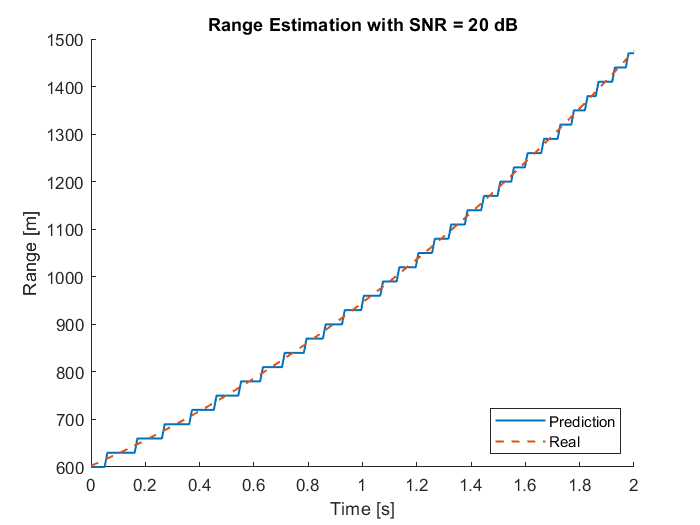

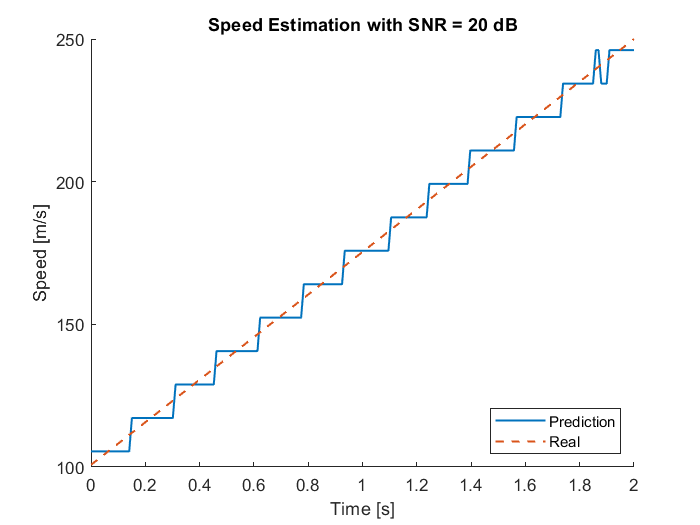

radobj.dSNR = 20; % dB
radobj = update_parameters(radobj);
result_struct_5 = runSim(radobj, sim_duration);
RadarSimulator.plot_range_speed_pred(result_struct_5, radobj)